3.1    (插值多项式）实时脚本

由张志涌编写、修改于 2023.1。

x = 0:3;
y = [-5 -6 -1 16];
disp([x; y])

     0     1     2     3
    -5    -6    -1    16



V = vander(x)

V =      0     0     0     1
     1     1     1     1
     8     4     2     1
    27     9     3     1


c = V\y'

c =     1.0000
    0.0000
   -2.0000
   -5.0000


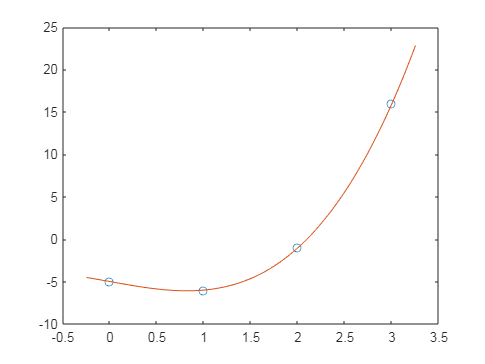

u = -.25:.01:3.25;
v = polyinterp(x,y,u);
plot(x,y,'o',u,v,'-')

symx = sym('x')

$$symx = x$$

P = polyinterp(x,y,symx)

$$P = \frac{x\,\left(x-1\right)\,\left(x-3\right)}{2}+5\,\left(\frac{x}{2}-1\right)\,\left(\frac{x}{3}-1\right)\,\left(x-1\right)+\frac{16\,x\,\left(\frac{x}{2}-\frac{1}{2}\right)\,\left(x-2\right)}{3}-6\,x\,\left(\frac{x}{2}-\frac{3}{2}\right)\,\left(x-2\right)$$

pretty(P)

x (x - 1) (x - 3)   / x     \ / x     \
----------------- + | - - 1 | | - - 1 | (x - 1)
        2           \ 2     / \ 3     /

         / x   1 \
       x | - - - | (x - 2) 16
         \ 2   2 /                / x   3 \
   5 + ---------------------- - x | - - - | (x - 2) 6
                  3               \ 2   2 /



P = simplify(P)

$$P = x^{3}-2\,x-5$$

x = 1:6;
y = [16 18 21 17 15 12];
disp([x; y])

     1     2     3     4     5     6
    16    18    21    17    15    12



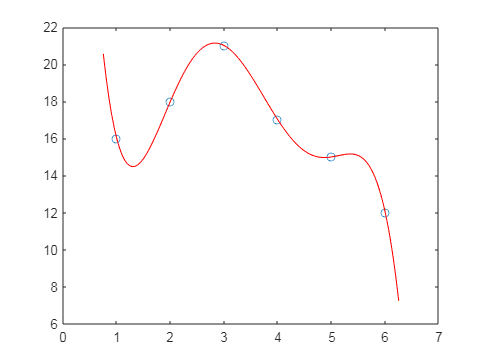

u = .75:.05:6.25;
v = polyinterp(x,y,u);
plot(x,y,'o',u,v,'r-');